clc;

clear;

imds = imageDatastore('dataset','IncludeSubfolders',true,'LabelSource','foldernames');

[trainGestureData, testGestureData] = splitEachLabel(imds, 0.90,'randomize');

layers = [imageInputLayer([128 128 3])

convolution2dLayer(5,20)

reluLayer

maxPooling2dLayer(2,'Stride',2)

fullyConnectedLayer(2)

softmaxLayer

classificationLayer()];

options = trainingOptions('sgdm', 'Plots', 'training-progress','LearnRateSchedule', 'piecewise', 'LearnRateDropFactor', 0.2, 'LearnRateDropPeriod', 5, 'MiniBatchSize', 300)

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.0100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.2000
             LearnRateDropPeriod: 5
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 30
                   MiniBatchSize: 300
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn: []
   

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:18 |       55.56% |      11.9390 |      1.0000e-04 |
|      30 |          30 |       00:00:22 |      100.00% |   0.0000e+00 |      3.2000e-08 |
|========================================================================================|
Training finished: Max epochs completed.


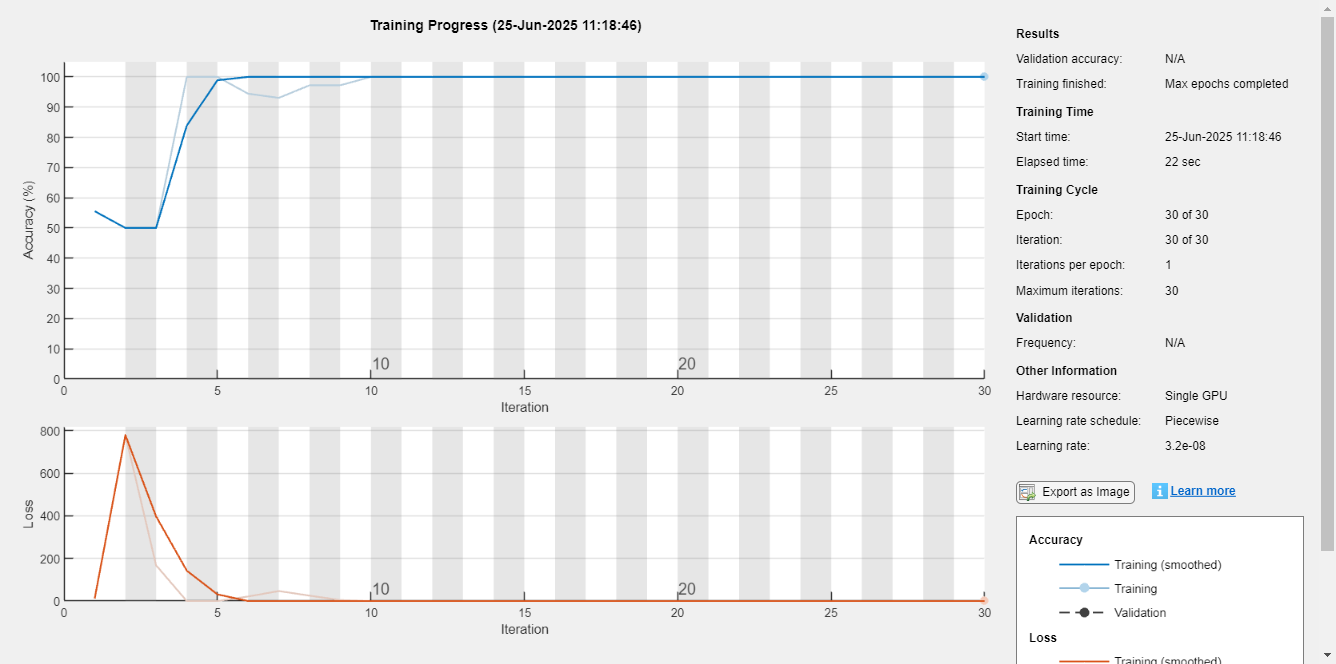

options.MaxEpochs = 30;

options.InitialLearnRate=0.0001;

convnet = trainNetwork(trainGestureData,layers,options);


save('trainedNet.mat','convnet')
